# LAB 5: ANGULAR VELOCITY CONTROL FOR DC MOTOR

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Hongtao Xu';
Students.ID = '260773785';
%---------------------------------------

## **0. Objectives**

In this lab, we will design an angular velocity state-feedback controller to track a desired reference signal. First, we will run an open-loop experiment to get an understanding about the normal system dynamics. Second, we will design a theoretical state-feedback controller based on a DC Motor model. Finally, we will tune the gains of the controller on the Virtual Motor to account for modeling uncertainties and sensor noise.

To initiate a connection with the virtual motor, run the following:

Motor = VirtualMotor();

## **1. A State-Space Representation of DC Motor**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown in the following

<<fig_dcmotorshematic.png>>

We can model the DC motor using the armature current $i$ and the angular speed $\omega$. The dynamics of the DC motor are given by the following two coupled differential equations:


$$ J \displaystyle \frac{d \omega}{dt} + b \omega = K_t i $$



$$ L \displaystyle \frac{d i}{dt} + R i = v - K_e \omega $$


where the parameters are defined as follow

Param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
Param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
Param.L = 0.018; % Electric inductance (H)
Param.R = 8.4; % Terminal resistance (Ohm)
Param.J = 2e-05; % Rotor moment of inertia (kg.m2)
Param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

From these differential equations we can represent the DC Motor model by the following state-space representation


$$ \displaystyle \frac{d}{dt}x(t) = \pmatrix{ -\displaystyle \frac{b}{J}
& \displaystyle \frac{K_t}{J} \cr -\displaystyle \frac{K_e}{L} &
-\displaystyle \frac{R}{L} } x(t) + \pmatrix{ 0 \cr \displaystyle
\frac{1}{L} } v(t) $$


where $v(t)$ is the voltage and the state vector contains the angular velocity $\omega(t)$ and the current $i(t)$


$$ x(t) = \pmatrix{ \omega(t) \cr i(t) } $$


Note that if we think of the angular velocity $\omega(t)$ as the output of this system, then $C = \pmatrix{1 & 0}$ and


$$ \omega(t) = C x(t) $$


In this case, the transfer function from the voltage $v(t)$ to the angular velocity $\omega(t)$ is given by


$$ G_o(s) = C (s I - A)^{-1} B $$


The state-space representation of the DC Motor can be written as

A = [ ...
    -Param.b / Param.J, Param.Kt / Param.J; ...
    -Param.Ke / Param.L, -Param.R / Param.L];
B = [ ...
    0; ...
    1 / Param.L];
C = [1, 0];
D = 0;
Go = ss(A, B, C, D);
tf(Go)


ans =
 
        9.444e04
  --------------------
  s^2 + 466.7 s + 3234
 
Continuous-time transfer function.



## **2. Desired specifications**

The objective of this lab is to track a reference signal $\omega_{ref}$ while satisfying the following requirements:

- Overshoot less than 20%.

- 5%-settling time less than 0.25 seconds.

- Steady state gain of 1 $\pm$ 5%.

The Reference angular velocity is defined by the following:


$$ \omega_{ref}(t) = \begin{cases}  25, & 0 \leq t < 5 \\ 75,  & t \geq
5\end{cases}$$


In `MATLAB` we define $\omega_{ref}$ by:

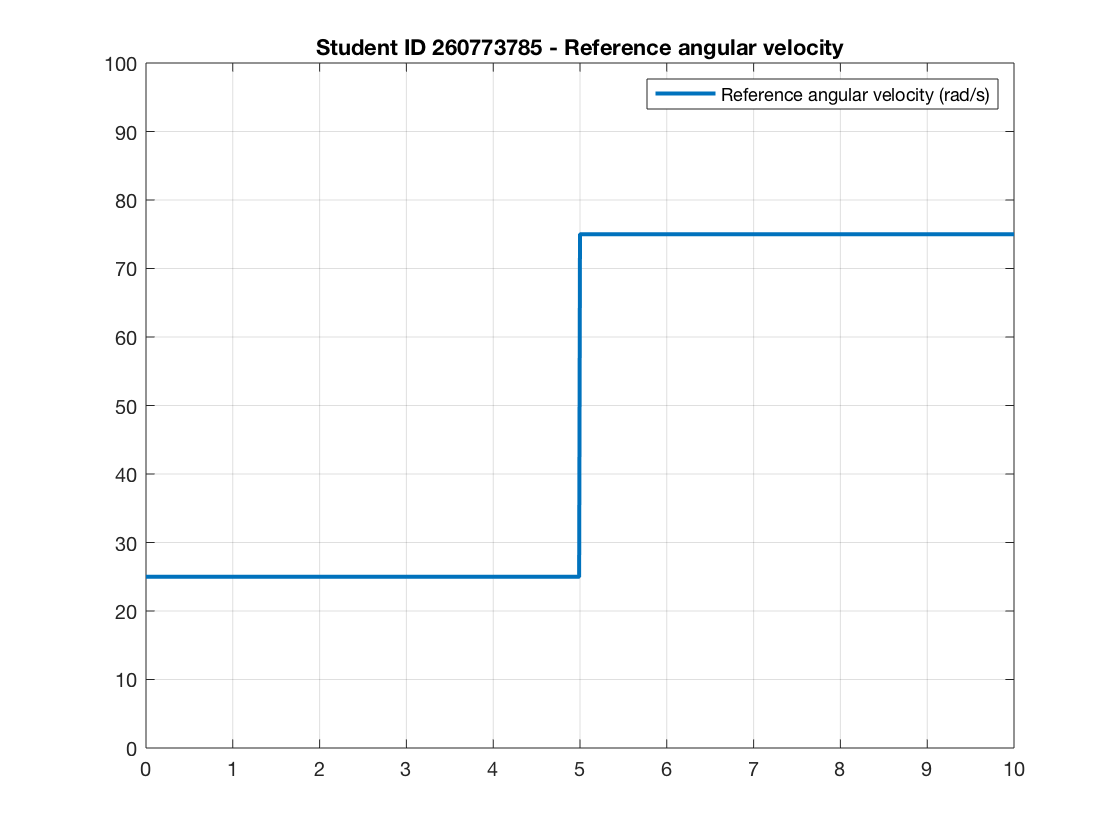

T = 10; % Simulation duration
dt = 0.01; % Simulation step time
t = (0:dt:T)'; % Time array
TStart = 5; % Step start
wRef = zeros(size(t));
wRef(t < TStart) = 25; % rad/s
wRef(t >= TStart) = 75; % rad/s

figure;
clf;
plot(t, wRef, 'LineWidth', 2.0)
legend('Reference angular velocity (rad/s)');
xlim([0, T])
ylim([0, 100])
title(sprintf('Student ID %s - Reference angular velocity', Students.ID));
grid on

## **3. Open-loop Experiment**

The state-space open-loop system is presented below.

<<fig_lab04_openloopdiagram.png>>

The gain $N_o$ is used to compensate for the open-loop DC gain, such as the total gain from $\omega_{ref}$ to $\omega$ is one.

## *Question 1 (2 marks)*

Complete the following code to run the DC Motor in open-loop in such a way that the angular velocity $\omega(t)$ follows the desired angular velocity signal $\omega_{ref}$

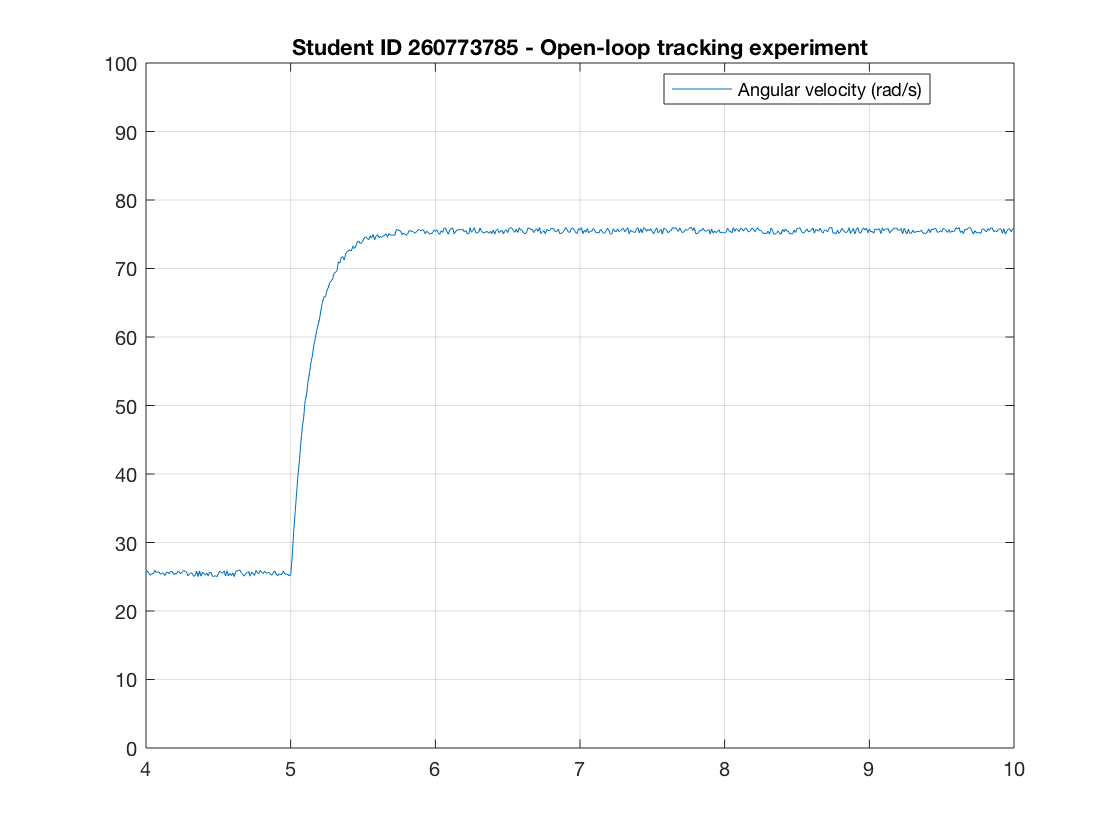

N_o=1/(C*inv(-A)*B);

Motor.reset();
v = N_o * wRef;

    
Motor.input(v);
Motor.wait(T);
Motor.off();

% Get results of driving Virtual DC Motor
v = Motor.voltage(Motor.time <= T);
i = Motor.current(Motor.time <= T);
w = Motor.velocity(Motor.time <= T);

% Plot results
figure;
clf;


% [Answer here] Superpose the angular velocity w and the reference wRef
plot(t,w)

legend('Angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart - 1, T])
ylim([0, 100])
title(sprintf('Student ID %s - Open-loop tracking experiment', Students.ID));
grid on

## *Question 2 (0.5 marks)*

Based on the plot above, determine if all the requirements are satisfied. Justify your answer.

Deponds on the simulation data collected before, the Ts is not satisfied because Ts is not meeting the requirements of 0.25s. All the other conditions are satisfied. 

## **4. Closed-Loop Simulation Experiment**

The closed-loop system is presented in the following figure.

<<fig_lab04_clsoedloopdiagram1.png>>

The full-state feedback control law is defined as follow


$$v(t) = N_c \omega_{ref} - K x(t)$$


where gain $K$ is a 1 by 2 matrix and the gain $N_c$ is forward gain that will ensure achieving $\omega_{ref}$ at steady state.

Actually, this diagram is equivalent to an open-loop diagram but with a different state transition matrix $A_{cl} = A-BK$

<<fig_lab04_clsoedloopdiagram2.png>>

Doing a state feedback with gain $K$ is equivalent to changing the system dynamics from $A$ to $A-BK$. Recall that the eigenvalues of a state transition matrix $A$ are the poles of the system.

We want to choose $K$ to specify the new poles of the closed-loop system $A-BK$ in a way that satisfies the desired specifications

- Overshoot less than 20%.

- 5%-settling time less than 0.25 seconds.

Then we will choose $N_c$ similarly to the open-loop section to satisfy the steady state requirements:

- Steady state gain of 1 $\pm$ 5%.

## *Question 3 (2 marks)*

Calculate the desired poles that satisfies the specifications (Use formula sheet for transient response of 2nd order system in myCourses if needed). And find the gain $K$ that place the poles of $A-BK$ at the desired poles (Use `place`).

den = [1 23.9974 692.674];
tf1 = tf (1,[1 23.9974 692.674])


tf1 =
 
          1
  ------------------
  s^2 + 24 s + 692.7
 
Continuous-time transfer function.



p = pole(tf1)

p =  -11.9987 +23.4245i
 -11.9987 -23.4245i


K = place(A,B,p)

K =    -0.0267   -7.9689


p1d = p(1);
p2d = p(2);

## *Question 4 (1 mark)*

- The closed-loop transfer function is


$$ G_c(s) = C (sI - (A-BK))^{-1} B $$


- What is the value of the DC gain of the closed-loop system.

- What is the value $N_c$ needed to compensate for the DC gain of the closed-loop system.

dcGainCL = C*inv(-(A-B*K))*B

dcGainCL = 136.3476

Nc = 1/dcGainCL

Nc = 0.0073

## *Question 5 (1 mark)*

Complete the following to sim)ulate angular velocity control with state feedback that tracks the desired $\omega_{ref}$.

Gc = ss((A-B*K),B,C,D)


Gc =
 
  A = 
            x1       x2
   x1    -0.05     1700
   x2  -0.4068   -23.95
 
  B = 
          u1
   x1      0
   x2  55.56
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




wSim = lsim(Gc,Nc*wRef,t)

wSim =          0
    0.7960
    2.9042
    5.9154
    9.4528
   13.1874
   16.8484
   20.2275
   23.1779
   25.6103


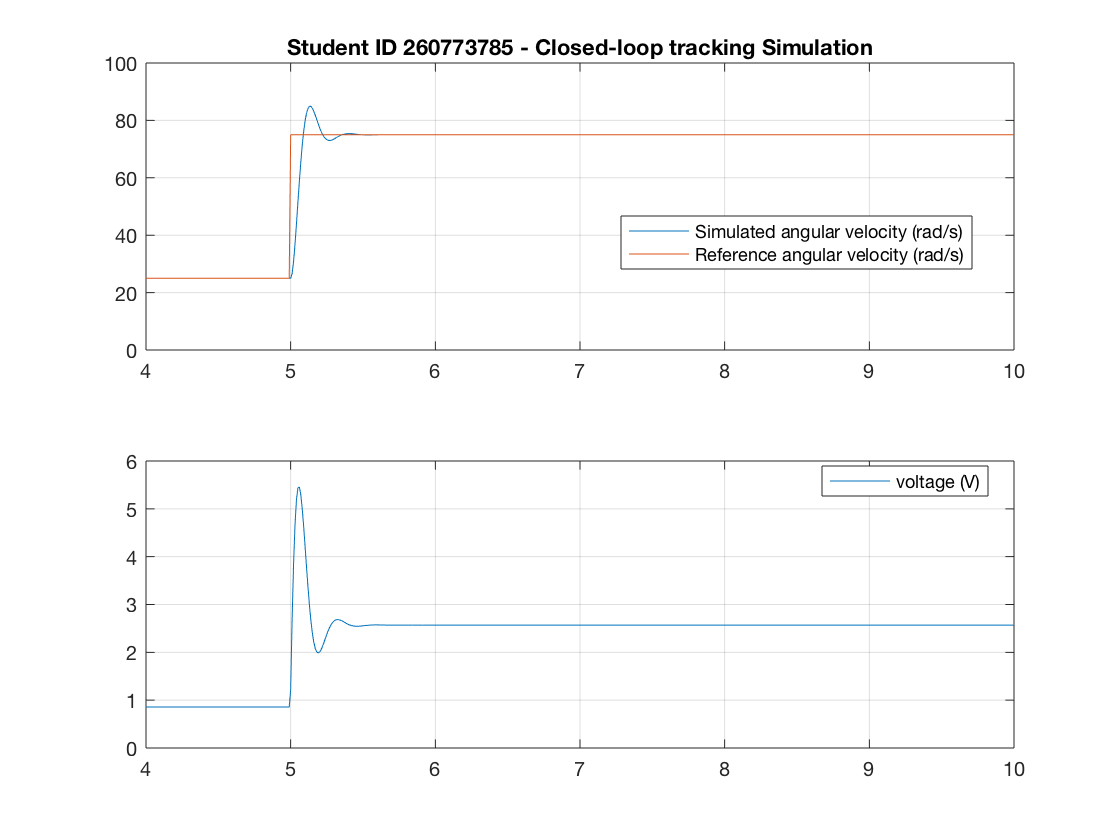



% We also simulate the voltage for visualization
vSim = -lsim(ss(Gc.A, Gc.B, eye(2), Gc.D), Nc*wRef, t) * K' + Nc * wRef;

figure;
clf;

subplot(2, 1, 1)

plot(t,wSim)
hold on
plot(t,wRef)

legend('Simulated angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart-1, T])
ylim([0, 100])
grid on
title(sprintf('Student ID %s - Closed-loop tracking Simulation', Students.ID));

subplot(2, 1, 2)
plot(t,vSim)

legend('voltage (V)', 'location', 'best');
xlim([TStart-1, T])
grid on

## *3.2. Closed-loop Experiment*

In order to control the virtual DC Motor, we need to take into account the sampling time $\delta t$. For this, we generate a discrete control law that achieves the desired poles.

Go_d = c2d(Go, dt, 'zoh'); % get the equivalent discrete open-loop system
Kd = place(Go_d.A, Go_d.B, [exp(p1d*dt), exp(p2d*dt)]);
Nd = 1 / (Go_d.C * (eye(2) - Go_d.A + Go_d.B * Kd)^(-1) * Go_d.B);

The gains $K_d$ and $N_d$ are the discrete equivalent of the gains $K$ and $N_c$. we will use these gains ($K_d$ and $N_d$) instead to control the virtual DC Motor.

Observe that now in closed-loop the value of the voltage (the control law) changes every time depending on the new value of $x(t)$, or in other words $\omega(t)$ and $i(t)$. To do this we will create a `for` loop that will loop over the time signal $t$. At every instant: # we will wait for the Motor time to sync with our time signal, using the `wait` command. # we will read new values of $\omega(t)$ and $i(t)$. # we will generate the new voltage to send. # we will send the voltage using `input` command.

## *Question 6 (2 marks)*

Complete the following to test the state feedback controller for tracking the desired $\omega_{ref}$. Observe that the control starts at time $t \geq T_{Start}$.

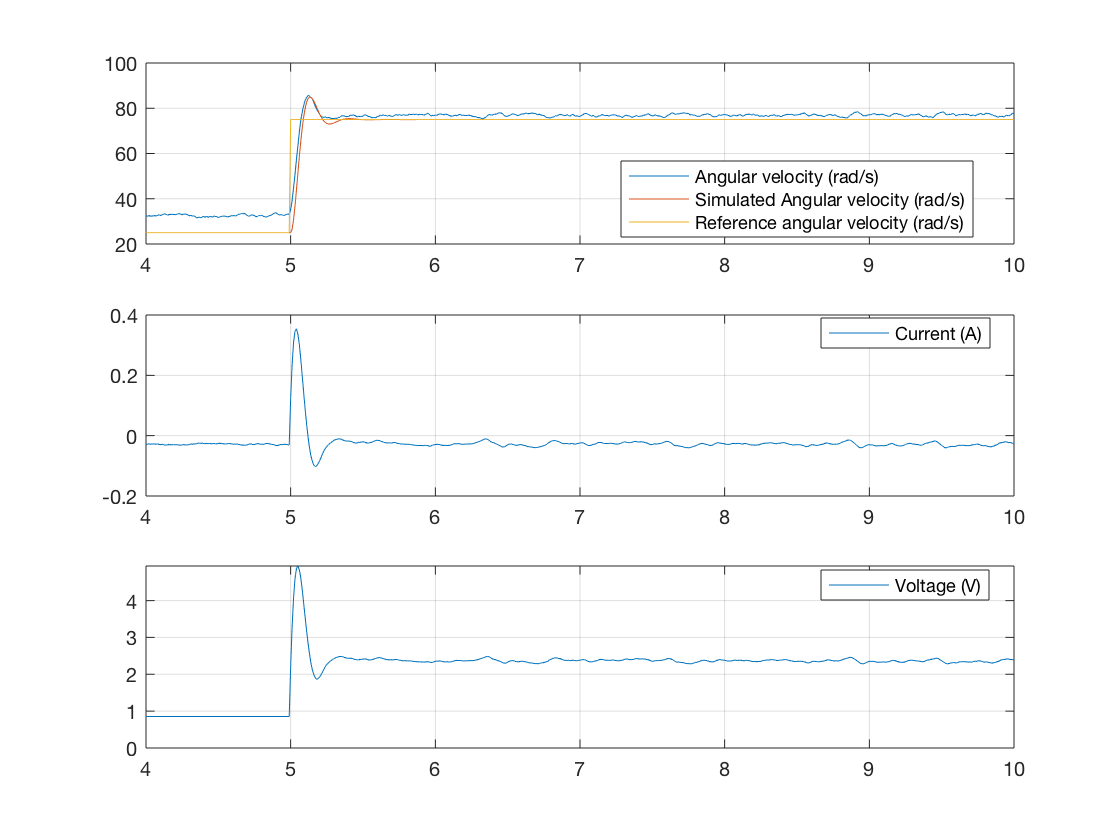

% Run the experiment
Motor.reset();
for n = 1:length(t)
    Motor.wait(t(n));
    w_ = Motor.velocity_final; % the final reading of velocity by sensor
    i_ = Motor.current_final; % the final reading of current by sensor
    x = [w_;i_];
    
    if t(n) < TStart % We only run 
        v_ = wRef(n)* N_o;
    else
        % [Answer here] Write the state feedback controller equation
        v_ = wRef(n)*Nd - Kd*x;


    end
    Motor.input(v_);
end
Motor.off();

% Get results of Virtual DC Motor
v = Motor.voltage(Motor.time <= T);
i = Motor.current(Motor.time <= T);
w = Motor.velocity(Motor.time <= T);

% Plot results
figure;
clf;

subplot(3, 1, 1)
title(sprintf('Student ID %s - Closed-loop tracking experiment', Students.ID));
% [Answer here] Superpose angular velocity and the velocity reference
plot(t,w)
hold on
plot(t,wSim)
plot(t,wRef)
legend('Angular velocity (rad/s)', ...
    'Simulated Angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart - 1, T])
grid on

subplot(3, 1, 2)
% [Answer here] Plot current
plot(t,i)
legend('Current (A)', 'location', 'best');
xlim([TStart - 1, T])
grid on

subplot(3, 1, 3)
% [Answer here] Plot voltage
plot(t,v)

legend('Voltage (V)', 'location', 'best');
xlim([TStart - 1, T])
grid on

## *Question 7 (0.5 marks)*

Based on the plot above, determine if all the requirements are satisfied. Justify your answer.

% No, Ts is too large and overshoot is too small so that requirements are
% not satisfied 

## *Question 8 (1 mark)*

Can you tune the value of the gain $N_d$ and $K_d$ to get the required performance. 

When you finish tuning, plot the final graph and fill up your final performances.

NdTuned = Nd;
KdTuned = [Kd(1), Kd(2)];

Motor.reset();
% [Answer here] Run the experiment use
for n = 1:length(t)
    Motor.wait(t(n));
end
Motor.off();


% Get results of Virtual DC Motor
v = Motor.voltage(Motor.time <= T);
i = Motor.current(Motor.time <= T);
w = Motor.velocity(Motor.time <= T);

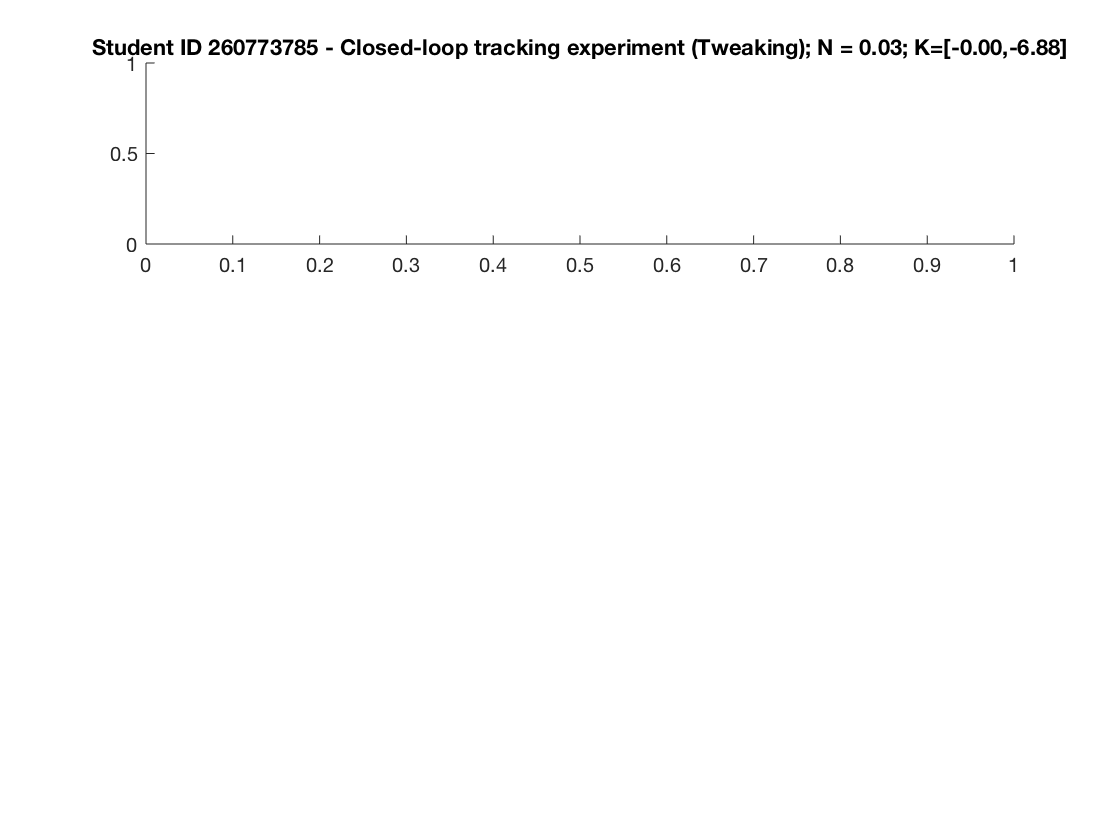

Error using plot
Vectors must be the same length.

% Plot new results
figure;
clf;

subplot(3, 1, 1)
title(sprintf('Student ID %s - Closed-loop tracking experiment (Tweaking); N = %04.2f; K=[%04.2f,%04.2f]', ...
    Students.ID, NdTuned, KdTuned));
plot(t,w)
hold on
plot(t,wSim)
plot(t,wRef)
% [Answer here] Superpose the angular velocity and the velocity reference

legend('Angular velocity (rad/s)', ...
    'Simulated Angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart - 1, T])
grid on

subplot(3, 1, 2)
% [Answer here] Plot current
plot(t,i)

legend('Current (A)', 'location', 'best');
xlim([TStart - 1, T])
grid on

subplot(3, 1, 3)
% [Answer here] Plot voltage
plot(t,v)

legend('Voltage (V)', 'location', 'best');
xlim([TStart - 1, T])
grid on

% [Answer here] Final performance obtained:

settlingTime % in seconds
overshoot % as a percentage [0 - 100]
steadyStateError % as a percentage [0 - 100]

if settlingTime <= 0.25 && ...
        overshoot <= 20 && ...
        steadyStateError <= 1

Cannot find an exact (case-sensitive) match for 'settlingTime'

The closest match is: settlingtime in /Applications/MATLAB_R2019b.app/toolbox/signal/signal/settlingtime.m

    disp('All requirements are satisfied')
else
    disp('Not all requirements are satisfied')
end